# Example 2.2, `Gaussian Random Vector`

Nicholas O'Donoughue 1 July 2019

`Consider the test`


$$\begin{array}{ll}\mathcal{H}_0: & {\bf z}\sim\mathcal{CN}\left(\theta_0,\sigma_n^2{\bf I}\right)\\
\mathcal{H}_1: & {\bf z}\sim\mathcal{CN}\left(\theta_1,\sigma_n^2{\bf I}\right)
\end{array}
\end{equation}$$


`Derive the optimal detector and analyze its performance.`

## Solution

`For simplicity, we introduce a ``vectorized`` form of the complex Gaussian ``PDF``.`

	
$$f_\theta(\bf z) = \pi^{-N}\sigma_n^{-2N}\exp\left\{\frac{-1}{\sigma_n^2}\left(\bf z-\theta\right)^H\left(\bf z-\theta\right)\right\}$$


`We compute the log likelihood ratio by plugging (2.16) into (2.12) for both `$\mathcal{H}_1$` and `$\mathcal{H}_0$.


$$	\ell(\bf z) = c + \Re\left\{\frac{2}{\sigma_n^2}\left(\theta_1-\theta_0\right)^H\bf z + \frac{1}{\sigma_n^2}\left(\theta_1+\theta_0\right)^H\left(\theta_0-\theta_1\right)\right\}$$


`where the term ``c`` collects all of the constants in the log likelihood ratio that are independent of the input ``z`` and can be ignored. For simplicity, we define the terms`

   
$$\begin{array}{rlc}
	\bf w &=& \frac{1}{\sigma_n^2}\left(\theta_1-\theta_0\right)\\
	\theta^\ast &=& \frac{1}{2}\left(\theta_1+\theta_0\right)\\
	d^2 &=& \sigma_n^2\bf w^H\bf w
\end{array}$$


`and rewrite the log likelihood ratio`


$$	\ell(\bf z) = \Re\left\{\bf w^H\left(\bf z - \theta^\ast\right)\right\}$$


`The test statistic `$\ell(\bf z)$` is the real component of a linear combination of complex Gaussian random variables (the elements of ``z``), so it is distributed as a Gaussian random variable. Thus, we can re-express the binary hypothesis problem`

	
$$\begin{array}{ll}\mathcal{H}_1: & \ell(\bf z) \sim \mathcal{N}\left(\frac{d^2}{2},d^2\right)\\
	\mathcal{H}_0 : & \ell(\bf z) \sim \mathcal{N}\left(-\frac{d^2}{2},d^2\right)
	\end{array}
$$


`Recall the `$P_{\mathrm{FA}}$` from (2.13), and note that it is the inverse of the cumulative distribution function (``CDF``) under ``$\mathcal{H}_0$``. The ``CDF`` of a Gaussian random variable with mean value `$\mu$` and variance `$\sigma_n^2$` is`


$$	F(x) = \frac{1}{2}\left(1 + \mathrm{erf}\left(\frac{x-\mu}{\sigma_n\sqrt{2}}\right)\right)
$$


`where `$\mathrm{erf}(x)$` is the ``error function``, defined`


$$	\mathrm{erf}(x) = \frac{2}{\sqrt{\pi}}\int_0^x e^{-t^2} dt$$


`and `$\mu$` and `$\sigma_n^2$` are the mean and variance, respectively. Thus,`


$$\begin{array}{rcl}
	P_{\mathrm{FA}} &=& 1 - F(\eta) \\
	&=& \frac{1}{2}\left(1-\mathrm{erf}\left(\frac{\eta+d^2/2}{d\sqrt{2}}\right)\right)
\end{array}$$


`To solve for `$\eta$`, we merely invert (2.26)`


$$	\eta = d\sqrt{2} \mathrm{erfinv}\left(1-2P_{\mathrm{FA}}\right)-\frac{d^2}{2}$$


`\end``{equation}`

`where `$x=\mathrm{erfinv}(y)$` is the parameter ``x`` that satisfies `$y=\mathrm{erf}(x)$`. `

`Once a threshold `$$\eta$ $ `is selected, we can repeat the process using the ``PDF`` of `$\ell(\bf z)$` under `$$\mathcal{H}_1$$` to compute the probability of detection `$$\left(P_{\mathrm{D}}\right)$$


$$	P_\mathrm{D} = \frac{1}{2}\left(1-\mathrm{erf}\left(\frac{\eta-d^2/2}{d\sqrt{2}}\right)\right)

$$


`To further illustrate the relationship between `$$P_{\mathrm{FA}}$$` and `$$P_\mathrm{D}$$`, we can plug the solution for the `$$\eta$$` in (2.27) into (2.28).`


$$	P_\mathrm{D} = \frac{1}{2}\left(1-\mathrm{erf}\left(\mathrm{erfinv}\left(1-2P_\mathrm{FA}\right)-d/\sqrt{2}\right)\right)
$$


`For a given `$$P_\mathrm{FA}$$` the achievable `$$P_\mathrm{D}$$` is given by the distance `$$d^2$$` of the two distributions. This distance term measures how much overlap there is between the distributions of `$$\ell(\bf z)$$` under the two hypotheses. The less overlap there is, the better the detector can perform for a given `$$P_\mathrm{FA}$$`. `

`We plot this relationship for a few representative values of `$$d^2$$`. This plot is often referred to as a ``receiver operating characteristics`` (``ROC``) curve.`

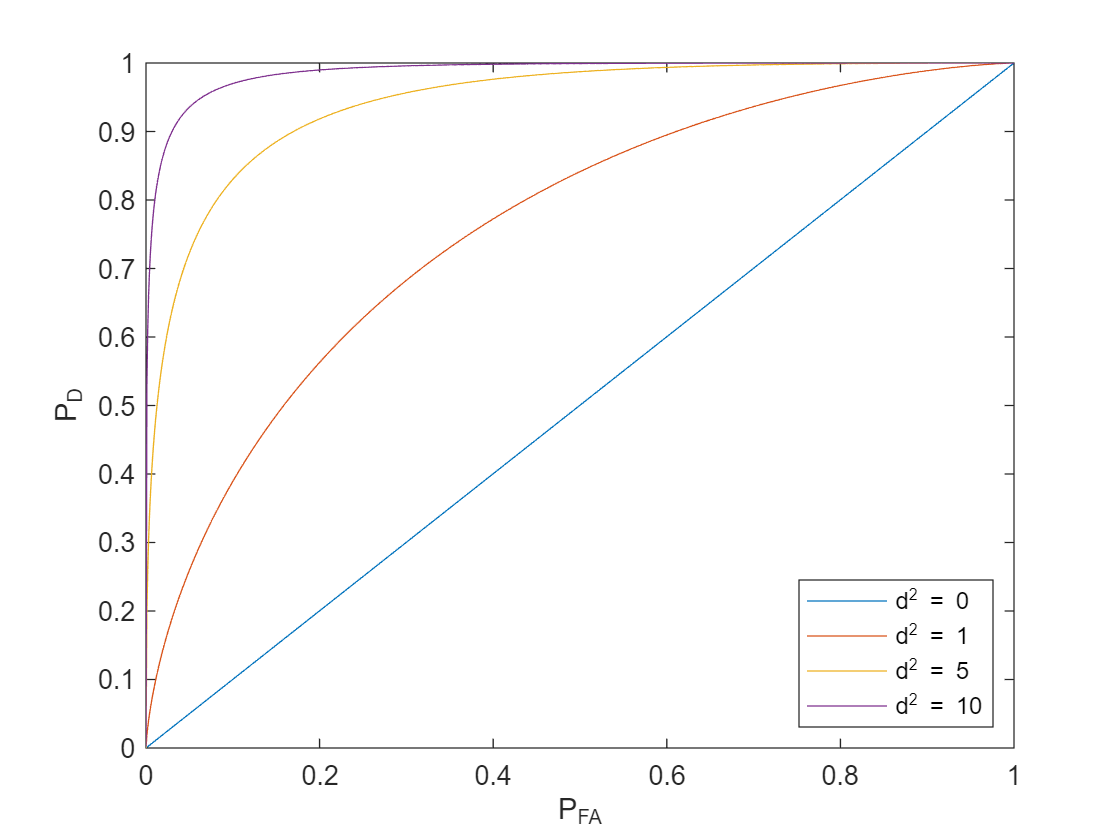

% Set up PFA and SNR vectors
pfa = linspace(1e-9,1,1001);
d2_vec = [1e-6,1,5,10]; % Use 1e-6 instead of 0, to avoid NaN

% Use ndgrid to simplify the code
[PFA,D2] = ndgrid(pfa,d2_vec);

% Compute the threshold eta using MATLAB's built-in error function erf(x) 
% and inverse error function erfinv(x).
eta = sqrt(2*D2).*erfinv(1-2*PFA)-D2/2;

% Compute the probability of detection
PD = .5*(1-erf((eta-D2/2)./sqrt(2*D2)));

% Plot the ROC curve
fig=figure;
plot(pfa,PD);

% Axes Labels
ylabel('P_D');xlabel('P_{FA}');

% Legend
legendStr = arrayfun(@(x) sprintf('d^2 = %d',round(x)),d2_vec,'UniformOutput',false);
legend(legendStr,'Location','SouthEast');

% Align the axes
xlim([0,1]);ylim([0 1]);